## Tutorial 1: Statistics Module

In this tutorial you will set up your first linear model with BrainStat. To this end, we will load some sample data from the ABIDE dataset. Note that,contrary to the results shown in our manuscript, we are only using a few sites to reduce computation time in this tutorial. As such the results shown here differ from those reported in our manuscript. To get identical results, simply set `sites` to `nan`. 

But before we get started, please note that this tutorial requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. 

sites = ["PITT", "OLIN", "OHSU"];
[cortical_thickness, demographics] = fetch_abide_data('sites', sites);
[surf_left, surf_right] = fetch_template_surface('civet41k');

mask = fetch_mask('civet41k');

Lets have a look at the cortical thickness data. To do this, we will use the surface plotter included with BrainSpace. Note that we use a recent version of BrainSpace in this tutorial (released on 16 July, 2021). If you've installed an older version please update before continuing. Lets plot mean thickness. Note that we've defined a function, `pretty_plot`, at the end of this file to make the plots a little prettier when they're embedded inside live scripts. If you run this tutorial outside of the live scripts you'll want to comment out the `pretty_plot` lines.

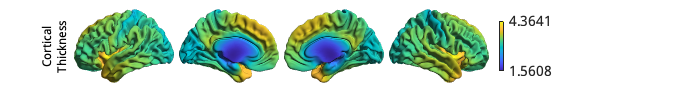

obj = plot_hemispheres(...
    mean(cortical_thickness)',  ...
    {surf_left, surf_right}, ...
    'labeltext', {{'Cortical', 'Thickness'}} ...
); 
pretty_plot(obj);

Next, lets see whether cortical thickness is related to age in our sample data. To this end we can create a linear model with BrainStat. First we declare the behavioral variables as `FixedEffects`. Once, that's done we can create the model by simply adding the terms together. Lets set up a model with age and patient status as fixed effects.

% Change the encoding of patient/control from 1/2 to strings.  
conversion = ["Patient"; "Control"];
demographics.DX_GROUP = conversion(demographics.DX_GROUP);

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
term_patient = FixedEffect(demographics.DX_GROUP);
model = term_age + term_patient;
disp(model)

  116×4 FixedEffect array with properties:

     names: ["Age"    "intercept"    "Control"    "Patient"]
    matrix: [116×4 double]



As you can see, model contains two properties: the names of each variable and a matrix containing the effects in a observation-by-variable matrix. 

Beside simple fixed effects, we may also be interested in interaction effects. We can add these to the model by multiplying terms. Lets create a model with an interaction between age and patient status.

model_interaction = 1 + term_age + term_patient + ...
    term_age * term_patient;

Now, imagine we have some cortical marker (e.g. cortical thickness) for each subject, and we want to evaluate whether this marker changes with age whilst correcting for effects of patient status. To do this, we can use the model we defined before, and a contrast in observations (here: age). Then we simply initialize an SLM model and fit it to the cortical thickness data. Note that the fitting may take a few minutes.

contrast_age = demographics.AGE_AT_SCAN;

BrainStatModel = SLM( ...
   model, ...
   contrast_age, ...
   'surf', 'civet41k', ...
   'correction', {'rft', 'fdr'}, ...
   'mask', mask);
BrainStatModel.fit(cortical_thickness);

We can access the outcome of this model through its properties. Lets plot the t-values and the vertexwise p-values derived from a random field theory correction.

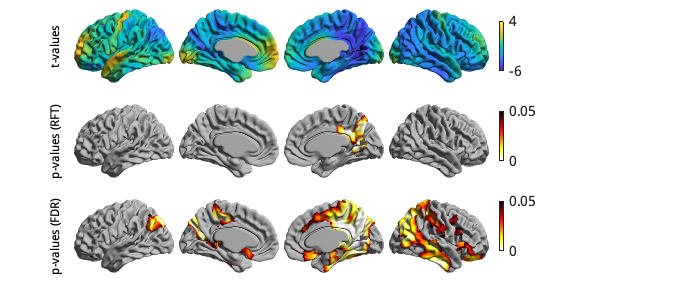

to_plot1 = [BrainStatModel.t', BrainStatModel.P.pval.P', BrainStatModel.Q'];
to_plot1(~mask,:) = inf;

plot1 = plot_hemispheres(...
    to_plot1,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values (RFT)', 'p-values (FDR)'} ...
);

plot1.colormaps({[parula; .7 .7 .7], ...
    [flipud(hot); .7 .7 .7], ...
    [flipud(hot); .7 .7 .7]});
plot1.colorlimits([-6, 4; 0, 0.05; 0, 0.05]);
pretty_plot(plot1);

BrainStat also allows for assessing significant clusters and peaks. The data on clusters are stored in tables inside BrainStatModel.P.clus and information on the peaks is stored in BrainStatModel.P.peak. If a two-tailed test is run (BrainStat defaults to two-tailed), a table is returned for each tail. The first table uses the contrast as provided, the second table uses the inverse contrast. If a one-tailed test is performed, then only a single table is returned. Lets print the first 15 rows of the inverted contrast cluster table. 

disp(BrainStatModel.P.clus{2}(1:15, :))

    clusid    nverts     resels         P     
    ______    ______    ________    __________

       1       8738        20.96    7.4502e-08
       2       1088        1.597    0.00061997
       3        492      0.64076       0.03337
       4        431      0.54829      0.050165
       5         64      0.21429       0.21632
       6         24        0.153       0.27915
       7         98      0.13461        0.3008
       8         43      0.11565       0.32453
       9          9      0.11245       0.32867
      10         21     0.083554         0.368
      11          2     0.041479       0.43119
      12          2     0.039791       0.43387
      13         13     0.027494       0.45367
      14          1     0.023942       0.45949
      15          1     0.022462       0.46193



Here, we see that cluster 1 contains 8738 vertices and is significant at a p-value of 7.45e-08. Clusters are sorted by p-value; later clusters will generally be smaller and have higher p-values. Lets now have a look at the peaks within these clusters. 

disp(BrainStatModel.P.peak{2}(1:15, :))

      t       vertid    clusid        P           yeo7   
    ______    ______    ______    __________    _________

    6.3155    72883       1       7.3046e-06    "Visual" 
    6.2384    72887       1       1.0292e-05    "Visual" 
    5.8728    79402       1       5.0832e-05    "Visual" 
     5.872    79524       1       5.1004e-05    "Visual" 
    5.8695    79387       1       5.1545e-05    "Visual" 
    5.8315    41573       1       6.0726e-05    "Visual" 
    5.7759    79361       1       7.6883e-05    "Visual" 
     5.747    79346       1       8.6891e-05    "Visual" 
    5.4913    43386       1        0.0002529    "Visual" 
    5.4565    79553       1       0.00029191    "Visual" 
    5.4314    50635       1       0.00032245    "Visual" 
    5.4171    71146       1       0.00034265    "Default"
    5.3522    711

Within cluster 1, we are able to detect several peaks. The most significant peak (t=6.3155) occurs at vertex 72883, which is inside the visual network as defined by the Yeo-7 networks. Note that the Yeo network membership is only provided if the surface is specified as a template name as we did here. For custom surfaces, or pre-loaded surfaces (as we will use below) this column is omitted. 

By default BrainStat uses a two-tailed test. If you want to get a one-tailed test, simply specify it in the SLM model initialization with `'two_tailed', false`. Note that the one-tailed test will test for positive t-values. If you want to test for negative t-values, simply invert the contrast. We may hypothesize based on prior research that cortical thickness decreases with age, so we could specify this as follows. Note the minus in front of `contrast_age` to test for decreasing thickness with age.

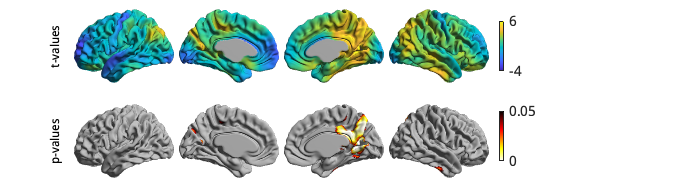

BrainStatModel_onetailed = SLM(...
    model, ...
    -contrast_age, ...
    'correction', 'rft', ...
    'surf', {surf_left, surf_right}, ...
    'mask', mask, ...
    'two_tailed', false ...
);
BrainStatModel_onetailed.fit(cortical_thickness);

to_plot2 = [BrainStatModel_onetailed.t', ...
    BrainStatModel_onetailed.P.pval.P'];
to_plot2(~mask,:) = inf;

plot2 = plot_hemispheres(...
    to_plot2,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values'} ...
);

plot2.colormaps({[parula; .7 .7 .7], [flipud(hot); .7 .7 .7]});
plot2.colorlimits([-4, 6; 0, 0.05]); 
pretty_plot(plot2)

Similarly, we could also use the patient/control status as a contrast, instead of age. This would work as follows:

contrast_patient = model.Patient - model.Control; 
BrainStatModel_patient = SLM( ...
   model, ...
   contrast_patient, ...
   'surf', 'civet41k', ...
   'correction', 'rft', ...
   'mask', mask);
BrainStatModel_patient.fit(cortical_thickness);

Now, imagine that instead of using a fixed effects model, you would prefer a mixed effects model wherein the scanning site is a random variable. This is simple to set up. All you need to do is initialize the site term with the `MixedEffect` class, all other code remains identical.

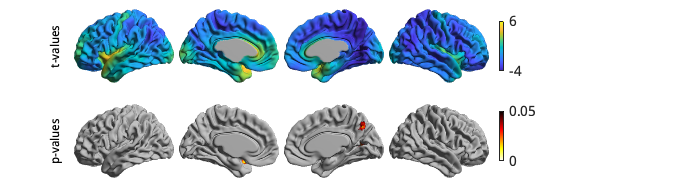

random_site = MixedEffect(demographics.SITE_ID);
model_random = term_age + term_patient + random_site;
BrainStatModel_random = SLM(model_random, contrast_age, ...
    'surf', {surf_left, surf_right}, 'mask', mask, 'correction', 'rft');
BrainStatModel_random.fit(cortical_thickness)

to_plot3 = [BrainStatModel_random.t', BrainStatModel_random.P.pval.P'];
to_plot3(~mask,:) = inf;

plot3 = plot_hemispheres(...
    to_plot3,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values'} ...
);

plot3.colormaps({[parula; .7 .7 .7], [flipud(hot); .7 .7 .7]});
plot3.colorlimits([-4, 6; 0, 0.05]); 
pretty_plot(plot3);

It appears that, after correction for site as a random variable, the significant results are far more localized. That concludes the basic usage of the BrainStat for statistical models. In the next tutorial we'll show you how to use the context decoding module.

function pretty_plot(obj)
    % Makes the BrainSpace plots prettier inside live scripts. 
    obj.handles.figure.Units = 'pixels';
    set(obj.handles.axes, 'Units', 'pixels')
    set(obj.handles.colorbar, 'Units', 'pixels');
    obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
    set(obj.handles.text, 'FontSize', 12);
    
    for jj = 1:size(obj.data, 2) % variates
        obj.handles.colorbar(jj).Position = [...
            500, ...
            30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
            5, ...
            50];
        for ii = 1:4 % views
            obj.handles.axes(jj, ii).Position = [...
                75 + (ii-1)*105, ...
                (size(obj.data, 2) * 95) - jj*95, ...
                100, ...
                100];
        end
    end
end